## Trabalho 1 PID:

#### Vinicius Rodrigues de Souza Fiedler Garcia RA: 211020681

### **1)**

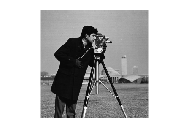


I = imread("cameraman.tif");
I = im2gray(I);
imshow(I);

### **2)**

J = I;
[altura,largura] = size(J);
nPixels = altura * largura;

### **3)**

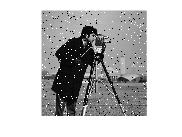

P = 0.05;
J = imnoise( I ,'salt & pepper',P);
imshow(J);

3.1 Selecione um P máximo

pMAX =0.65;

**Criando Filtro da Média e outras Variaveis auxiliares**

Filtro_Media = fspecial("average",3);
InformacaoMedia = zeros(pMAX / 0.05,10);
InformacaoMediana = zeros(pMAX / 0.05,10);
gMax = 255;

**4)**

J_median = imfilter(J,Filtro_Media);
J_mean = medfilt2(J);

l1{1} = I;
l1{2} = J;
l1{3} = J_mean;
l1{4} = J_median;
lista_imagens{81} = I;
montage(l1);

**5)**

5.1 Erro Máximo

%% Erro máximo da média
maior = 0;
for i = 1 : altura
    for j = 1 : largura
        valor = I(i,j) - J_mean(i,j);
        valor = abs(valor);
        maior = max(valor,maior);
    end
end
InformacaoMedia(1,1) = maior;

%% Erro máximo da Mediana

maior = 0;
for i = 1 : altura
    for j = 1 : largura
        valor = I(i,j) - J_median(i,j);
        valor = abs(valor);
        maior = max(valor,maior);
    end
end
InformacaoMediana(1,1) = maior;

5.2 Erro médio absoluto

%% Erro médio absoluto da média
valor = sum(I,"all") - sum(J_mean,"all");
soma = abs(valor);
InformacaoMedia(1,2) = soma/nPixels;

%% Erro médio absoluto da mediana
valor = sum(I,"all") - sum(J_median,"all");
soma = abs(valor);
InformacaoMediana(1,2) = soma/nPixels;

5.3 Erro médio quadrático

%% Erro médio quadrático da média
somaQuadraticaMedia = 0;
erro = double(0);
for i = 1 : altura
    for j = 1 : largura
        valor = (I(i,j) - J_mean(i,j));
        erro = double(valor * valor);
        somaQuadraticaMedia = somaQuadraticaMedia + erro;
    end
end
InformacaoMedia(1,3) = somaQuadraticaMedia/nPixels;


%% Erro médio quadrático da mediana
somaQuadraticaMediana = 0;
for i = 1 : altura
    for j = 1 : largura
        valor = (I(i,j) - J_median(i,j));
        erro = double(valor * valor);
        somaQuadraticaMediana = somaQuadraticaMediana + erro;
    end
end

InformacaoMediana(1,3) = somaQuadraticaMediana/nPixels;

5.4 Raiz do erro médio quadrático

%% Raiz do erro médio quadrático da media
InformacaoMedia(1,4) = sqrt(InformacaoMedia(1,3));

%% Raiz do erro médio quadrático da mediana
InformacaoMediana(1,4) = sqrt(InformacaoMediana(1,3));

5.5 Erro médio quadrático normalizado

somaQuadraticaDeI = 0;

for i = 1 : altura
    for j = 1 : largura
        valor = (I(i,j));
        erro = double(valor * valor);
        somaQuadraticaDeI = somaQuadraticaDeI + erro;
    end
end

%% Erro médio quadrático normalizado da Media

InformacaoMedia(1,5) = somaQuadraticaMedia/somaQuadraticaDeI;

%% Erro médio quadrático normalizado da Mediana

InformacaoMediana(1,5) = somaQuadraticaMediana/somaQuadraticaDeI;


5.6 Relação sinal-ruído de pico (PSNR)

%% Numerador da divisão
numerador = nPixels * gMax * gMax;

%% PSNR da Média
denominadorMedia = somaQuadraticaMedia;
psnrMedia = 10 * log10(numerador/denominadorMedia);
InformacaoMedia(1,6) = psnrMedia;

%% PSNR da Mediana
denominadorMediana = somaQuadraticaMediana;
psnrMediana = 10 * log10(numerador/denominadorMediana);
InformacaoMediana(1,6) = psnrMediana;

5.7 Covariância

%% Auxiliares
mediaOriginal = sum(I, 'all')/nPixels;
mediaDaMedia  = sum(J_mean, 'all')/nPixels;
mediaDaMediana  = sum(J_median, 'all')/nPixels;

%% Covariância da media

somaCovMedia = 0;
for i = 1:altura
    for j = 1:largura
            error = cast((I(i, j) - mediaOriginal) * (J_mean(i, j) - mediaDaMedia), "double");
            somaCovMedia = somaCovMedia + error;
    end
end

covMedia = somaCovMedia/nPixels;
InformacaoMedia(1,7) = covMedia;

%% Covariância da Mediana

somaCovMediana = 0;
for i = 1:altura
    for j = 1:largura
            error = cast((I(i, j) - mediaOriginal) * (J_median(i, j) - mediaDaMediana), "double");
            somaCovMediana = somaCovMediana + error;
    end
end

covMediana = somaCovMediana/nPixels;
InformacaoMediana(1,7) = covMediana;

5.8 Coeficiente de correlação

%% Correlação da Media

desvioPadrao = std2(I);
dpMedia = std2(J_mean);


CorrelacaoMedia = InformacaoMedia(1,7) / desvioPadrao * dpMedia;
InformacaoMedia(1,8) = CorrelacaoMedia;

%% Correlação da Mediana

desvioPadrao = std2(I);
dpMediana = std2(J_median);


CorrelacaoMediana = InformacaoMediana(1,7) / desvioPadrao * dpMediana;
InformacaoMedia(1,8) = CorrelacaoMediana;

5.9 Coeficiente de Jaccard

%% Da Media
somaJaccard = 0;
for i = 1 : altura
    for j = 1 : largura
         if J_mean(i,j) == I(i,j)
             somaJaccard = somaJaccard + 1;
         end
    end
end

CoeficienteJaccardMedia = somaJaccard / nPixels;
InformacaoMedia(1,9) = CoeficienteJaccardMedia;

%% Da Mediana
somaJaccard = 0;
for i = 1 : altura
    for j = 1 : largura
         if J_median(i,j) == I(i,j)
             somaJaccard = somaJaccard + 1;
         end
    end
end

CoeficienteJaccardMediana = somaJaccard / nPixels;
InformacaoMediana(1,9) = CoeficienteJaccardMediana;


5.10 SSIM

%% Da media

InformacaoMedia(1,10) = ssim(J_mean,I);

%% Da mediana

InformacaoMediana(1,10) = ssim(J_median ,I);

### **6,7,8)**

**Preenchendo toda a tabela**

for i = 0.05 :0.05: pMAX
    % Modifica as imagens
    J = imnoise( I ,'salt & pepper',i);
    J_mean = imfilter(J,Filtro_Media);
    J_median = medfilt2(J);
   
    posicaoMat = uint32( i / 0.05);
    posimg = (posicaoMat - 1) * 4;

    % Coloca as imagens na lista
    lista_imagens{posimg + 1} = I;
    lista_imagens{posimg + 2} = J;
    lista_imagens{posimg + 3} = J_mean;
    lista_imagens{posimg + 4} = J_median;

    

    

    InformacaoMedia(posicaoMat,1) = erro_maximo(I,J_mean);
    InformacaoMedia(posicaoMat,2) = erro_medio_absoluto(I,J_mean);
    InformacaoMedia(posicaoMat,3) = erro_medio_quadratico(I,J_mean);
    InformacaoMedia(posicaoMat,4) = sqrt(InformacaoMedia(posicaoMat,3));
    InformacaoMedia(posicaoMat,5) = erro_medio_quadratico_normalizado(I,J_mean);
    InformacaoMedia(posicaoMat,6) = PsignalNR(I,J_mean);
    InformacaoMedia(posicaoMat,7) = covariancia(I,J_mean);
    InformacaoMedia(posicaoMat,8) = coeficiente_de_correlacao(I,J_mean);
    InformacaoMedia(posicaoMat,9) = coef_jaccard(I,J_mean);
    InformacaoMedia(posicaoMat,10) = ssim(J_mean,I);
    % InformacaoMedia(posicaoMat,11) = i;

    InformacaoMediana(posicaoMat,1) = erro_maximo(I,J_median);
    InformacaoMediana(posicaoMat,2) = erro_medio_absoluto(I,J_median);
    InformacaoMediana(posicaoMat,3) = erro_medio_quadratico(I,J_median);
    InformacaoMediana(posicaoMat,4) = sqrt(InformacaoMediana(posicaoMat,3));
    InformacaoMediana(posicaoMat,5) = erro_medio_quadratico_normalizado(I,J_median);
    InformacaoMediana(posicaoMat,6) = PsignalNR(I,J_median);
    InformacaoMediana(posicaoMat,7) = covariancia(I,J_median);
    InformacaoMediana(posicaoMat,8) = coeficiente_de_correlacao(I,J_median);
    InformacaoMediana(posicaoMat,9) = coef_jaccard(I,J_median);
    InformacaoMediana(posicaoMat,10) = ssim(J_median,I);
    % InformacaoMediana(posicaoMat,11) = i;

    
    

    
end

### 9)

montage(lista_imagens, 'Size' , [pMAX/0.05, 4]);

### 10)

rowNames="p "+ (0.05:0.05:pMAX)';
colNames=["ME" , "MAE" , " MSE" , " RMSE" , " NMSE " , " PSNR " , " COV " , " COR " , " JAC " , " SSIM "];
sTableMedia = array2table(InformacaoMedia,'RowNames',rowNames,'VariableNames',colNames);
sTableMediana = array2table(InformacaoMediana,'RowNames',rowNames,'VariableNames',colNames);
disp(sTableMedia);

              ME       MAE         MSE      RMSE       NMSE       PSNR      COV       COR        JAC        SSIM  
              ___    ________    ______    ______    ________    ______    ______    ______    _______    ________

    p 0.05    199     0.48808     17.14    4.1401    0.072064    35.791    144.73    142.98    0.33362     0.86025
    p 0.1     201     0.55757    18.171    4.2627    0.076396    35.537    144.36    142.76    0.32071     0.84553
    p 0.15    199      0.5795    19.224    4.3845    0.080822    35.292    143.99    142.73    0.31097      0.8265
    p 0.2     23

disp(sTableMediana);

              ME       MAE         MSE      RMSE      NMSE       PSNR      COV       COR         JAC        SSIM  
              ___    ________    ______    ______    _______    ______    ______    ______    _________    _______

    p 0.05    138     0.53595    50.072    7.0762    0.21052    31.135    139.48    129.28       0.1259    0.54445
    p 0.1     175    0.069656    64.306    8.0191    0.27036    30.048    136.23    121.72     0.079819    0.41225
    p 0.15    159     0.59018     73.64    8.5814    0.30961     29.46    133.86    115.74      0.05246    0.33501
    p 0.2     18

### 11)

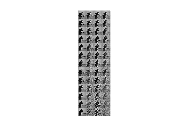

tiledlayout(5, 2);


for i = 1:10

    nexttile
    plot(InformacaoMedia(:, i));
    hold on;

    plot(InformacaoMediana(:, i));

    legend('Media', 'Mediana');

    title(colNames(i));
end

Funções do Trabalho

function [maior] = erro_maximo(img1,img2)
    [altura,largura] = size(img1);
    maior = 0;
    for i = 1 : altura
        for j = 1 : largura
            valor = img1(i,j) - img2(i,j);
            valor = abs(valor);
            maior = max(valor,maior);
        end
    end
end

function [resultado] = erro_medio_absoluto(img1,img2)
    [altura,largura] = size(img1);
    nPixels = altura * largura;
    valor = sum(img1,"all") - sum(img2,"all");
    soma = abs(valor);
    resultado = soma/nPixels;
end

function[resultado] = erro_medio_quadratico(img1,img2)
    somaQuadratica = 0;
    [altura,largura] = size(img1);
    nPixels = altura * largura;

    for i = 1 : altura
        for j = 1 : largura
            valor = (img1(i,j) - img2(i,j));
            erro = double(valor * valor);
            somaQuadratica = somaQuadratica + erro;
        end
    end

    resultado = somaQuadratica/nPixels;
end

function[resultado] = erro_medio_quadratico_normalizado(img1,img2)
    
somaQuadraticaDeI = 0;
    [altura,largura] = size(img1);
    nPixels = altura * largura;

    for i = 1 : altura
        for j = 1 : largura
            valor = (img1(i,j));
            erro = double(valor * valor);
            somaQuadraticaDeI = somaQuadraticaDeI + erro;
        end
    end
    resultado = erro_medio_quadratico(img1,img2) * nPixels / somaQuadraticaDeI;
end

function[resultado] = PsignalNR(img1,img2)

    [altura,largura] = size(img1);

    nPixels = altura * largura;

    numerador = nPixels * 255 * 255;
    
    denominadorMedia = erro_medio_quadratico(img1,img2) * nPixels;
    psnrMedia = 10 * log10(numerador/denominadorMedia);
    resultado = psnrMedia;

end

function[resultado] = covariancia(img1,img2)
    [altura,largura] = size(img1);
    nPixels = altura * largura;

    m1 = sum(img1, 'all')/nPixels;
    m2  = sum(img2, 'all')/nPixels;
    

    somaCovMedia = 0;
    for i = 1:altura
        for j = 1:largura
                error = cast((img1(i, j) - m1) * (img2(i, j) - m2), "double");
                somaCovMedia = somaCovMedia + error;
        end
    end
    
    covMedia = somaCovMedia/nPixels;
    resultado = covMedia;

end

function[resultado] = coeficiente_de_correlacao(img1,img2)
    desvioPadrao = std2(img1);
    dp2 = std2(img2);
    
    
    Correlacao= covariancia(img1,img2) / desvioPadrao * dp2;
    resultado = Correlacao;
end

function[resultado] = coef_jaccard(img1,img2) 

    [altura,largura] = size(img1);
    nPixels = altura * largura;

    somaJaccard = 0;
    for i = 1 : altura
        for j = 1 : largura
             if img1(i,j) == img2(i,j)
                 somaJaccard = somaJaccard + 1;
             end
        end
    end
    
    CoeficienteJaccard = somaJaccard / nPixels;
    resultado = CoeficienteJaccard;
end